Processing: path_without_obstacle.png


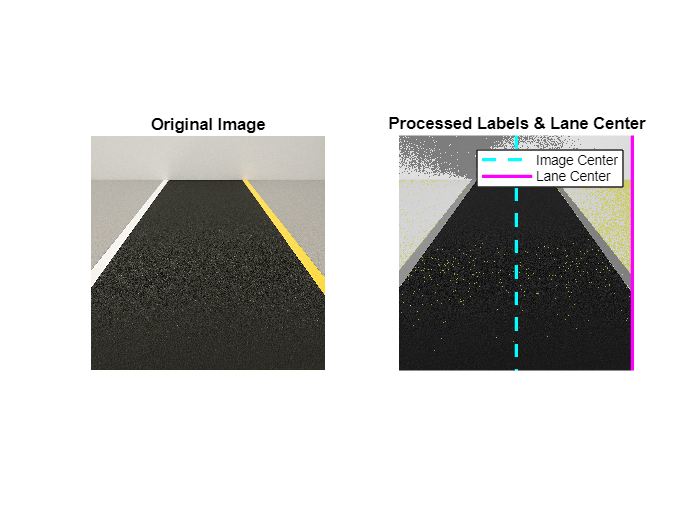

--- Results for: path_without_obstacle.png ---


  Lane Offset: 505.50 px (from image center)


  Lane Pixel Width: 1.0 px


  Obstacle Detected: true


  Obstacle Pixel Width: 205 px


  Obstacle Distance (A1.6): 0.95 m


--------------------------------------



Results saved to: C:\Users\Morri\Desktop\Robotics\Lab\Lab1\Report\SW\image-processing\path_without_obstacle_results.mat


Processing: path_with_obstacle.png


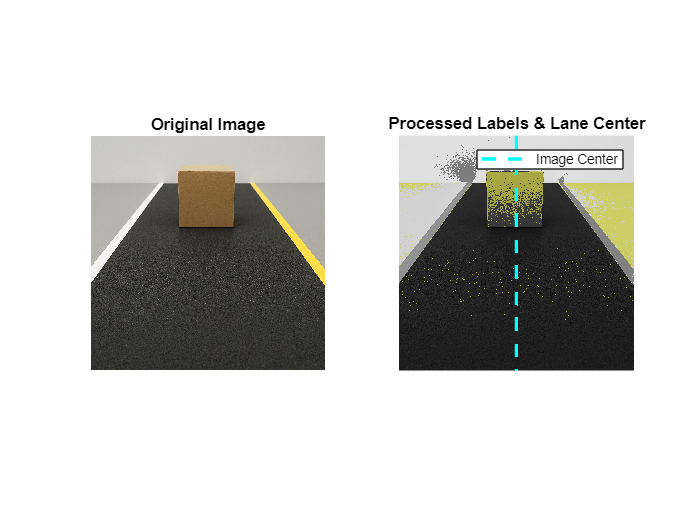

--- Results for: path_with_obstacle.png ---


  Lane Offset: NaN px (from image center)


  Lane Pixel Width: NaN px


  Obstacle Detected: true


  Obstacle Pixel Width: 205 px


  Obstacle Distance (A1.6): 0.95 m


--------------------------------------



Results saved to: C:\Users\Morri\Desktop\Robotics\Lab\Lab1\Report\SW\image-processing\path_with_obstacle_results.mat


Processing: smooth-60-left-turn.png


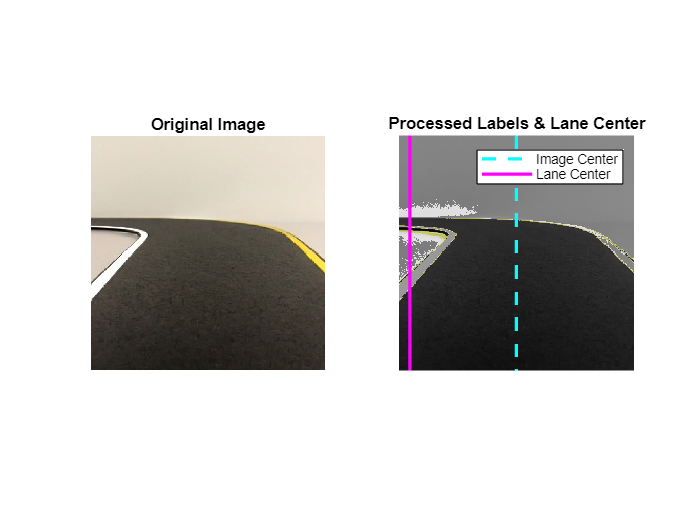

--- Results for: smooth-60-left-turn.png ---


  Lane Offset: -464.00 px (from image center)


  Lane Pixel Width: -86.0 px


  Obstacle Detected: false


--------------------------------------



Results saved to: C:\Users\Morri\Desktop\Robotics\Lab\Lab1\Report\SW\image-processing\smooth-60-left-turn_results.mat


Processing: yawed-20-right-straight-lane.png


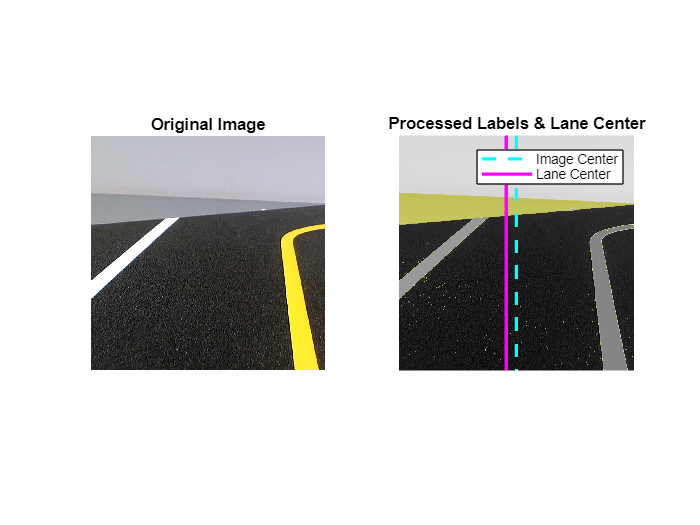

--- Results for: yawed-20-right-straight-lane.png ---


  Lane Offset: -44.00 px (from image center)


  Lane Pixel Width: -888.0 px


  Obstacle Detected: true


  Obstacle Pixel Width: 186 px


  Obstacle Distance (A1.6): 1.05 m


--------------------------------------



Results saved to: C:\Users\Morri\Desktop\Robotics\Lab\Lab1\Report\SW\image-processing\yawed-20-right-straight-lane_results.mat


%%FSD Robot Car Simulation core computer vision algorithms

% Clear workspace and function cache
clear;
clc;
clear functions;
close all;

%% 1. Constants and Configuration
% ---
% Define all parameters for the simulation.

% Image paths
IMAGE_PATH = "C:/Users/Morri/Desktop/Robotics/Lab/Lab1/Report/SW/image-processing/";

% Define the test images
imageFiles = [
    "path_without_obstacle.png",       % Scenario 1: Straight, clear
    "path_with_obstacle.png",         % Scenario 2: Straight, obstacle
    "smooth-60-left-turn.png",         % Scenario 3: Curved lane
    "yawed-20-right-straight-lane.png" % Scenario 4: Car at an angle
];

% Pixel Labelling Thresholds
CONSTS.Tw = 205; % White lane threshold
CONSTS.Ty = 175; % Yellow lane threshold
CONSTS.To = 100; % Obstacle threshold

% Camera and World Parameters
% Note: Images are 1024x1024
CONSTS.IMG_WIDTH = 1024;
CONSTS.IMG_HEIGHT = 1024;
CONSTS.CAM_FOV_DEGREES = 60;          % From lab example
CONSTS.LANE_WIDTH_METERS = 0.6;       % From lab setup
CONSTS.OBSTACLE_REAL_WIDTH_METERS = 0.2; % 20cm cube

%% 2. Main Processing Loop
% ---
% This loop iterates through each test image, processes it, 
% displays the results, and saves the results to a .mat file.

for i = 1:length(imageFiles)
    % --- Load Image ---
    currentFile = imageFiles(i);
    imgPath = fullfile(IMAGE_PATH, currentFile);
    
    try
        img = imread(imgPath);
    catch e
        warning('Failed to read image: %s. Skipping.', imgPath);
        continue;
    end
    
    % --- Run Full Vision Pipeline ---
    fprintf('Processing: %s\n', currentFile);
    results = processFsdImage(img, CONSTS, currentFile);
    
    % --- Display Results ---
    displayResults(img, results);
    
    % --- Print to Console ---
    fprintf('--- Results for: %s ---\n', currentFile);
    fprintf('  Lane Offset: %.2f px (from image center)\n', results.lane_offset_px);
    fprintf('  Lane Pixel Width: %.1f px\n', results.pixel_width_lane);
    fprintf('  Obstacle Detected: %s\n', string(results.obstacle_detected));
    if results.obstacle_detected
        fprintf('  Obstacle Pixel Width: %.0f px\n', results.obstacle_width_px);
        fprintf('  Obstacle Distance (A1.6): %.2f m\n', results.obstacle_distance_m);
    end
    fprintf('--------------------------------------\n\n');

    % *** NEW CODE TO SAVE RESULTS ***
    % This saves the 'results' variable to a .mat file
    [~, name, ~] = fileparts(currentFile);
    saveName = sprintf('%s_results.mat', name);
    savePath = fullfile(IMAGE_PATH, saveName);
    save(savePath, 'results');
    fprintf('Results saved to: %s\n', savePath);
    % ********************************
    
end


%% 3. Local Functions
% =========================================================================
% (All the other functions: processFsdImage, labelPixels, 
% findLaneOffset, detectObstacle, estimateObjectSize, 
% estimateObjectDistance, and displayResults go here, exactly as 
% they were in the previous, working script).
% =========================================================================


function results = processFsdImage(img, CONSTS, currentFile)
%
% This is the main processing pipeline function. It accepts an image,
% a constants struct, and the current filename. It runs all the
% vision algorithms and returns a 'results' struct.
%

    % Add the image_path to the results struct
    results.image_path = currentFile;

    % Convert to grayscale for processing
    if size(img, 3) == 3
        Igray = rgb2gray(img);
    else
        Igray = img;
    end
    
    % A1.2: Label all pixels
    results.labels = labelPixels(Igray, CONSTS);
    
    % A1.3: Find lane offset
    [results.lane_offset_px, results.pixel_width_lane] = findLaneOffset(results.labels, CONSTS);
    
    % A1.4: Detect obstacle
    [results.obstacle_detected, r_coords, c_coords] = detectObstacle(results.labels, CONSTS);
    
    % A1.5 & A1.6: Estimate size and distance if obstacle exists
    if results.obstacle_detected
        % A1.5: Estimate object size
        [results.obstacle_width_px, results.obstacle_height_px] = estimateObjectSize(r_coords, c_coords);
        
        % A1.6: Estimate object distance
        results.obstacle_distance_m = estimateObjectDistance(results.obstacle_width_px, CONSTS);
    else
        results.obstacle_width_px = 0;
        results.obstacle_height_px = 0;
        results.obstacle_distance_m = Inf;
    end
end

% ---
% ALGORITHM A1.2: PIXEL LABELLING
% ---
function labels = labelPixels(Igray, CONSTS)
    % This function implements the pixel grouping logic from A1.2
    labels = zeros(size(Igray), 'uint8');
    
    % Apply thresholds from lab manual
    labels(Igray > CONSTS.Tw) = 1; % White
    labels(Igray > CONSTS.Ty & Igray <= CONSTS.Tw) = 2; % Yellow
    labels(Igray > CONSTS.To & Igray <= CONSTS.Ty) = 3; % Obstacle
    % 0 = Background (default)
end

% ---
% ALGORITHM A1.3: LANE KEEPING
% ---
function [offset_px, pixel_width_lane] = findLaneOffset(labels, CONSTS)
    % Implements A1.3 to find the car's offset from the lane center
    
    % Initialize default return values
    offset_px = NaN;
    pixel_width_lane = NaN;
    
    % Analyze middle rows (as suggested by lab)
    % Sample at 60% down the image
    sample_row = round(CONSTS.IMG_HEIGHT * 0.6);
    
    % Get all white (1) and yellow (2) pixel columns in that row
    white_pixels_idx = find(labels(sample_row, :) == 1);
    yellow_pixels_idx = find(labels(sample_row, :) == 2);
    
    if isempty(white_pixels_idx) || isempty(yellow_pixels_idx)
        warning('Could not find both white and yellow lanes in sample row.');
        return;
    end
    
    % Find innermost lane positions (A1.3, Step 3)
    xl = max(white_pixels_idx);  % Innermost white pixel
    xr = min(yellow_pixels_idx); % Innermost yellow pixel
    
    % Calculate lane width and center in pixels (A1.3, Step 4)
    pixel_width_lane = xr - xl;
    xc = (xl + xr) / 2; % Lane center
    
    % Compute offset from image center (A1.3, Step 5)
    image_center_px = CONSTS.IMG_WIDTH / 2;
    offset_px = xc - image_center_px;
end

% ---
% ALGORITHM A1.4: OBSTACLE DETECTION
% ---
function [detected, r_coords, c_coords] = detectObstacle(labels, CONSTS)
    % Implements A1.4 to detect an object in the central region
    
    % Define the "central region" to check
    % Middle 20% of width, 50-70% down the image
    [rows, cols] = size(labels);
    r_start = round(rows * 0.5);
    r_end = round(rows * 0.7);
    c_start = round(cols * 0.4);
    c_end = round(cols * 0.6);
    
    % Extract the central region labels
    central_region_labels = labels(r_start:r_end, c_start:c_end);
    
    % Find all pixels labelled as "obstacle" (3)
    [r_coords, c_coords] = find(central_region_labels == 3);
    
    % Decision: Obstacle is present if any pixel is labelled as such
    detected = ~isempty(r_coords);
    
    % Adjust coordinates to be relative to the full image (for plotting)
    if detected
        r_coords = r_coords + r_start - 1;
        c_coords = c_coords + c_start - 1;
    end
end

% ---
% ALGORITHM A1.5: OBJECT SIZE ESTIMATION
% ---
function [width_px, height_px] = estimateObjectSize(r_coords, c_coords)
    % Implements A1.5 to find the pixel extent of the object
    
    if isempty(r_coords)
        width_px = 0;
        height_px = 0;
        return;
    end
    
    % Find horizontal (wo) and vertical (ho) extent
    min_c = min(c_coords);
    max_c = max(c_coords);
    width_px = max_c - min_c + 1;
    
    min_r = min(r_coords);
    max_r = max(r_coords);
    height_px = max_r - min_r + 1;
end

% ---
% ALGORITHM A1.6: OBJECT DISTANCE ESTIMATION
% ---
function distance_m = estimateObjectDistance(object_width_px, CONSTS)
    % Implements A1.6 to find the distance to the object
    
    % 1. Calculate Angular Size (theta_o)
    theta_o_deg = (object_width_px / CONSTS.IMG_WIDTH) * CONSTS.CAM_FOV_DEGREES;
    theta_o_rad = deg2rad(theta_o_deg);
    
    % 2. Get Real Size (wr)
    % The lab specifies a 20cm cube
    wr = CONSTS.OBSTACLE_REAL_WIDTH_METERS;
    
    % 3. Distance Formula (from A1.6)
    % Using the small-angle approximation from the lab
    if theta_o_rad == 0
        distance_m = Inf;
        return;
    end
    distance_m = wr / theta_o_rad;
end

% ---
% HELPER FUNCTION: DISPLAY RESULTS
% ---
function displayResults(img, results)
    % Create a figure to show the original image and the labelled output
    
    figure('Name', results.image_path);
    
    % Original Image
    subplot(1, 2, 1);
    imshow(img);
    title('Original Image', 'Interpreter', 'none');
    
    % Processed Image
    subplot(1, 2, 2);
    if size(img, 3) == 3
        Igray = rgb2gray(img);
    else
        Igray = img;
    end
    imshow(Igray);
    hold on;
    
    % Create color map for labels
    % 0:Black(BG), 1:White, 2:Yellow, 3:Red(Obstacle)
    label_colors = [0 0 0; 1 1 1; 1 1 0; 1 0 0];
    
    % Create an RGB overlay for labels
    label_overlay = label2rgb(results.labels, label_colors, 'k');
    
    % Overlay the labels with 50% transparency
    hImg = imshow(label_overlay);
    set(hImg, 'AlphaData', 0.4);
    
    % Get dimensions from image
    [rows, cols, ~] = size(img);
    
    % Plot Image Center
    img_center_px = cols / 2;
    line([img_center_px img_center_px], [1 rows], ...
         'Color', 'cyan', 'LineStyle', '--', 'LineWidth', 2);
    
    % Plot Lane Center
    if ~isnan(results.lane_offset_px)
        lane_center_px = img_center_px + results.lane_offset_px;
        line([lane_center_px lane_center_px], [1 rows], ...
             'Color', 'magenta', 'LineStyle', '-', 'LineWidth', 2);
        legend('Image Center', 'Lane Center');
    else
        legend('Image Center');
    end
    
    title('Processed Labels & Lane Center');
    hold off;
end